%==========================================================================
% Main script for weather data processing and PV performance analysis
%
% This script:
%   - Imports and cleans weather data for the last three years
%   - Imports station coordinates and plots them on a map
%   - Performs sunshine duration analysis per station and per year
%   - Computes EPOA and PV cell temperature
%   - Computes PV efficiency using a MEX function (pv_efficiency.c)
%
% Required files/functions:
%   - function_clean_data.m
%   - function_EPOA.m
%   - function_Tcell.m
%   - pv_efficiency.c (MEX source)
%   - coordonnees_stations.csv
%==========================================================================

clear; clc; close all;

% Part 1 : Import and clean the data
fprintf('-------------------- Part 1 : Import and clean the data --------------------\n');

-------------------- Part 1 : Import and clean the data --------------------



% Load and clean data from the last 3 years 
fprintf('...Loading and cleaning weather data...\n');

...Loading and cleaning weather data...


[cleaned_data_2024, cleaned_data_2023, cleaned_data_2022] = function_clean_data();

% Importing station coordinates
fprintf('...Importing station coordinates...\n');

...Importing station coordinates...



filename = 'coordonnees_stations.csv';
opts = detectImportOptions(filename, 'Delimiter',';', 'VariableNamingRule','preserve');
T = readtable(filename, opts);

% Part 2 : Map of stations
fprintf('-------------------- Part 2 : Map of stations --------------------\n');

-------------------- Part 2 : Map of stations --------------------


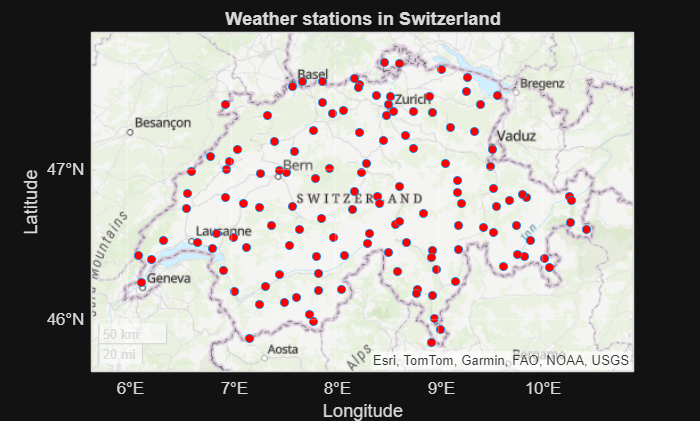


% Extract relevant columns from the coordinate table
altitude = T.('Hauteur de mesure m s. mer');    % station altitude [m]
lat = T.Latitude;                               % latitude  [deg]
lon = T.Longitude;                              % longitude [deg]
abreviation = string(T.('Abr.'));               % station abbreviation

% Create the figure and the map centered on Switzerland
figure
gx = geoaxes; 
geobasemap(gx,'topographic'); 
hold on

% Add station points
p = geoplot(gx, lat, lon, 'o', 'MarkerFaceColor','r', 'MarkerSize',5);
title('Weather stations in Switzerland')

% Define the information to display in data tips
p.DataTipTemplate.DataTipRows = [ ...
    dataTipTextRow('Abreviation', abreviation), ...
    dataTipTextRow('Altitude (m)', altitude), ...
    dataTipTextRow('Latitude', lat), ...
    dataTipTextRow('Longitude', lon)];

% Center the map around the stations
geolimits(gx, [min(lat)-0.2 max(lat)+0.2], [min(lon)-0.2 max(lon)+0.2])

% Part 3 : Sunshine analysis
fprintf('-------------------- Part 3 : Sunshine analysis --------------------\n');

-------------------- Part 3 : Sunshine analysis --------------------



Analysis for 2024 :



The sunniest station : OTL (10313 min)


Least sunny station : ELM (5174 min)


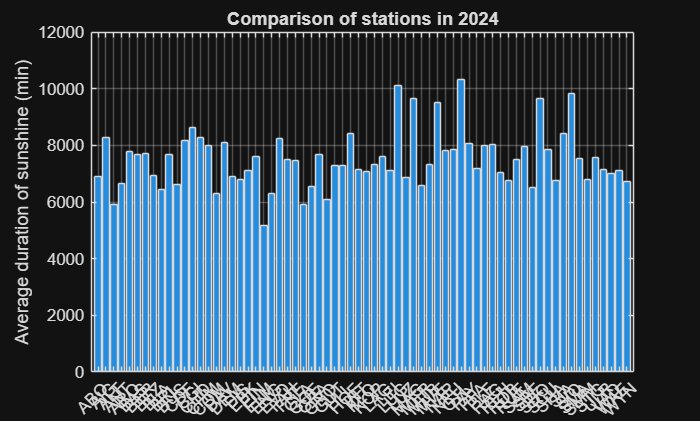


Analysis for 2023 :



The sunniest station : OTL (11726 min)


Least sunny station : ELM (6050 min)


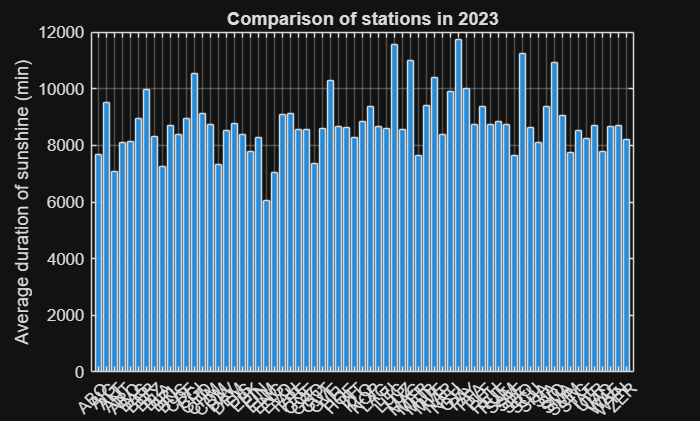


Analysis for 2022 :



The sunniest station : OTL (12887 min)


Least sunny station : ELM (6815 min)


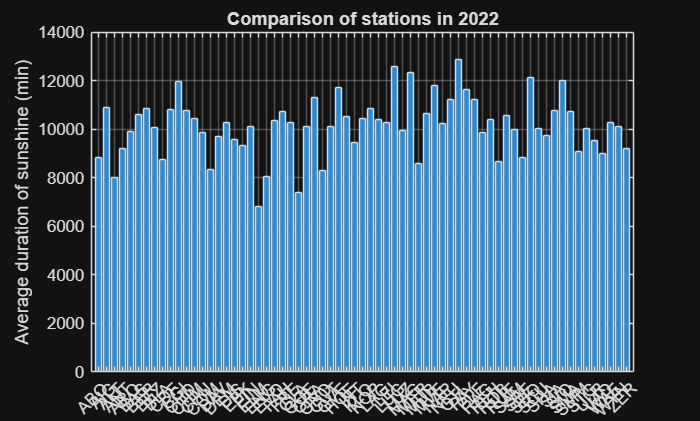


years = [2024, 2023, 2022];
cleaned_sets = {cleaned_data_2024, cleaned_data_2023, cleaned_data_2022};

for a = 1:numel(years)
    target_year = years(a);
    cleaned_data = cleaned_sets{a};

    fprintf('\nAnalysis for %d :\n', target_year);

    
    % Concatenate all station monthly tables into one global table
    % This allows computing overall statistics across stations for the given year.
    all_data = vertcat(cleaned_data{:});

    dates = all_data.Date;                 % timestamps (monthly records)
    sunshine_min = all_data.sre000m0;      % sunshine duration [min]
    sunshine_percent = all_data.sremaxmv;  % relative sunshine [%]

     % Build a year-month index to compute monthly averages across all stations
    year_month = datetime(year(dates), month(dates), 1);
    [unique_months, ~, month_idx] = unique(year_month);

    % Monthly mean sunshine duration across all stations 
    monthly_min = accumarray(month_idx, sunshine_min, [], @mean);
    monthly_percent = accumarray(month_idx, sunshine_percent, [], @mean);

    % Store monthly averages in a compact table 
    monthly_avg = table(unique_months, monthly_min, monthly_percent, ...
        'VariableNames', {'Date', 'mean_sre000m0', 'mean_sremaxmv'});
    monthly_avg = sortrows(monthly_avg, 'Date');

    % Global comparison between stations 
    % For each station, compute the mean sunshine duration over the 12 months of the year.
    station_names = all_data{:,1};           % station identifiers (first column)
    sre000m0_values = all_data.sre000m0;     % sunshine duration [min]
    tbl = table(station_names, sre000m0_values);
    station_avg = varfun(@mean, tbl, 'InputVariables','sre000m0_values', ...
        'GroupingVariables','station_names');

    % Identify the most and least sunny stations for the considered year
    [~, idxMax] = max(station_avg.mean_sre000m0_values);
    [~, idxMin] = min(station_avg.mean_sre000m0_values);

    fprintf('\nThe sunniest station : %s (%.0f min)\n', ...
        char(station_avg.station_names(idxMax)), station_avg.mean_sre000m0_values(idxMax));
    fprintf('Least sunny station : %s (%.0f min)\n', ...
        char(station_avg.station_names(idxMin)), station_avg.mean_sre000m0_values(idxMin));

    % Bar chart for station comparison (mean annual sunshine duration per station)
    figure('Name', ['Station comparison ' num2str(target_year)], 'NumberTitle', 'off');
    bar(categorical(station_avg.station_names), station_avg.mean_sre000m0_values);
    xtickangle(45);
    ylabel('Average duration of sunshine (min)');
    title(['Comparison of stations in ' num2str(target_year)]);
    grid on;
end

% Part 4 : Calculation of cell temperature
fprintf('-------------------- Part 4 : Calculation of cell temperature --------------------\n');

-------------------- Part 4 : Calculation of cell temperature --------------------



%  Calculation of the EPOA for each year
EPOA_2024 = function_EPOA(cleaned_data_2024, T) ;
EPOA_2023 = function_EPOA(cleaned_data_2023, T);
EPOA_2022 = function_EPOA(cleaned_data_2022, T);

% Calculation of PV cell temperature for each year
Tcell_2024 = function_Tcell(EPOA_2024, cleaned_data_2024);
Tcell_2023 = function_Tcell(EPOA_2023, cleaned_data_2023);
Tcell_2022 = function_Tcell(EPOA_2022, cleaned_data_2022);


fprintf('\nCalculations of EPOA and cell temperature completed for 2024, 2023 and 2022 \n');


Calculations of EPOA and cell temperature completed for 2024, 2023 and 2022 


% Part 5 : PV efficiency based on cell temperature
fprintf('-------------------- Part 5 : PV efficiency based on cell temperature --------------------\n');

-------------------- Part 5 : PV efficiency based on cell temperature --------------------



% Compile MEX file
mex pv_efficiency.c

Building with 'Microsoft Visual C++ 2022 (C)'.
MEX completed successfully.



years     = [2024, 2023, 2022];
Tcell_sets = {Tcell_2024, Tcell_2023, Tcell_2022};
stations_sets = {
    cellstr(Tcell_2024.Abbreviation_station)
    cellstr(Tcell_2023.Abbreviation_station)
    cellstr(Tcell_2022.Abbreviation_station)
};

% PV model parameters used in the C code (constant for all years)
fprintf('\nPV Efficiency Model Parameters\n');


PV Efficiency Model Parameters


fprintf('Technology                     : Monocrystalline Silicon (PERC, TOPCon)\n');

Technology                     : Monocrystalline Silicon (PERC, TOPCon)


fprintf('Reference efficiency (eta_ref) : 21.00 %%\n');

Reference efficiency (eta_ref) : 21.00 %


fprintf('Reference temperature (Tref)   : 25.0 °C\n');

Reference temperature (Tref)   : 25.0 °C


fprintf('Temperature coefficient beta   : 0.0045 1/°C\n');

Temperature coefficient beta   : 0.0045 1/°C


fprintf('Irradiance G                   : 1000 W/m²\n');

Irradiance G                   : 1000 W/m²


fprintf('Panel area A                   : 1 m²\n');

Panel area A                   : 1 m²



for k = 1:numel(years)
    an      = years(k);
    Tab     = Tcell_sets{k};

    % Extract relevant columns
    stations = Tab.Abbreviation_station;
    Tmean    = Tab.Tcell_annual_mean;

    % Convert to row vectors for C (strings)
    stations_C = strjoin("""" + stations + """", ", ");
    Tmean_C    = sprintf('%.4f, ', Tmean);
    Tmean_C(end-1:end) = []; % Remove trailing ", "

    fprintf('\nPV Efficiency Simulation – Year %d\n', an);
    fprintf('Stations (%d):\n', numel(stations));
    fprintf('  %s\n\n', stations_C);
    fprintf('Annual mean cell temperature (°C):\n');
    fprintf('  %s\n\n', Tmean_C);
    fprintf('Output file:\n');
    fprintf('  Efficiency_%d.csv\n\n', an);

    % CSV file name for this year
    filename = sprintf('Efficiency_%d.csv', an);

    % Call the MEX function (sorting + model + CSV export)
    [eta, P, Tcell_sorted, station_sorted] = pv_efficiency(Tmean, stations, filename);

end


PV Efficiency Simulation – Year 2024


Stations (68):


  "COM", "ABO", "AIG", "ALT", "ANT", "ARO", "RAG", "BAS", "BER", "BEZ", "BLA", "BUS", "CHD", "CHM", "DAV", "DEM", "DIS", "EBK", "EIN", "ELM", "ENG", "EVO", "FAH", "GRA", "GLA", "GOE", "GRO", "GUT", "HLL", "HOE", "INT", "KOP", "BRL", "CDF", "FRE", "LAG", "LEI", "OTL", "LUG", "LUZ", "MAG", "MER", "MVE", "MUB", "NAP", "NEU", "CGI", "PAY", "PFA", "PLF", "ROB", "RUE", "SBE", "SAM", "SHA", "SCU", "SIA", "SIO", "STG", "SMM", "SBO", "ULR", "VAD", "WAE", "WYN", "REH", "SMA", "KLO"



Annual mean cell temperature (°C):


  12.0160, 9.3685, 12.7916, 12.3780, 6.8380, 6.9369, 13.0152, 13.7139, 12.4287, 13.1569, 6.9884, 12.6867, 10.6504, 9.2900, 6.7853, 12.1096, 10.2407, 11.2238, 10.5449, 9.8330, 10.2743, 8.5559, 12.1233, 12.3748, 11.7560, 12.9408, 12.3778, 13.1684, 12.1612, 10.0195, 11.8449, 12.4067, 8.3441, 10.6015, 9.2738, 11.0877, 13.4392, 15.6150, 15.6525, 12.8992, 14.4268, 11.2347, 10.0868, 13.1254, 8.3358, 13.3880, 13.4881, 12.9741, 12.0255, 10.4576, 9.8090, 12.5788, 6.6210, 5.7742, 12.7303, 9.4811, 5.2899, 14.5829, 10.6758, 9.0264, 14.2138, 6.8102, 13.4517, 13.0105, 12.9773, 12.9241, 12.9606, 12.6483



Output file:


  Efficiency_2024.csv




PV Efficiency Simulation – Year 2023


Stations (67):


  "TAE", "COM", "ABO", "AIG", "ALT", "ANT", "ARO", "BAS", "BER", "BEZ", "BLA", "BUS", "CHD", "CHM", "DAV", "DEM", "DIS", "EBK", "EIN", "ELM", "ENG", "EVO", "FAH", "GVE", "GOE", "GRO", "GUT", "HLL", "HOE", "INT", "KOP", "BRL", "CDF", "FRE", "LAG", "LEI", "OTL", "LUG", "LUZ", "MAG", "MER", "MVE", "MUB", "NAP", "NEU", "CGI", "PAY", "PFA", "PLF", "RUE", "SBE", "SAM", "SHA", "SCU", "SIA", "SIO", "STG", "SMM", "SBO", "ULR", "VAD", "WAE", "WYN", "ZER", "REH", "SMA", "KLO"



Annual mean cell temperature (°C):


  13.3081, 13.0478, 9.4222, 13.1255, 12.8774, 7.0263, 7.3274, 14.3655, 12.9247, 13.5335, 6.9576, 13.4313, 11.0910, 9.7386, 6.8682, 12.7743, 10.6228, 12.1624, 10.7393, 9.9047, 10.2966, 8.9092, 12.6643, 14.3523, 13.5111, 13.1472, 13.5508, 12.6867, 10.1471, 12.1439, 12.7726, 8.8814, 11.0519, 9.6255, 11.5693, 13.8075, 16.5004, 16.0602, 13.1348, 15.3760, 11.6919, 10.5553, 13.5193, 8.4617, 14.3607, 13.9498, 13.6809, 12.2655, 11.0315, 13.2391, 7.4364, 6.4703, 13.2088, 9.7855, 5.7728, 14.9604, 10.8545, 9.1931, 14.9063, 7.3371, 13.6902, 13.4837, 13.4841, 7.3196, 13.4206, 13.5954, 12.8783



Output file:


  Efficiency_2023.csv




PV Efficiency Simulation – Year 2022


Stations (67):


  "COM", "ABO", "AIG", "ALT", "ANT", "ARO", "RAG", "BAS", "BER", "BEZ", "BLA", "CHD", "CHM", "CHU", "DAV", "DEM", "DIS", "EBK", "EIN", "ELM", "ENG", "EVO", "FAH", "GRA", "GVE", "GLA", "GOE", "GRO", "GUT", "HOE", "INT", "KOP", "CDF", "FRE", "LAG", "LEI", "OTL", "LUG", "LUZ", "MAG", "MER", "MVE", "MUB", "NAP", "NEU", "CGI", "PAY", "PLF", "ROB", "RUE", "SBE", "SAM", "SHA", "SCU", "SIA", "SIO", "STG", "SMM", "SBO", "ULR", "VAD", "WAE", "WYN", "ZER", "REH", "SMA", "KLO"



Annual mean cell temperature (°C):


  13.0590, 9.9136, 13.9278, 12.9029, 7.0966, 7.6603, 13.5398, 14.6733, 13.1174, 14.4096, 7.6613, 11.5028, 10.2740, 13.6127, 6.9107, 12.8365, 10.9216, 12.3467, 11.2677, 9.8630, 10.5687, 9.4717, 13.0575, 13.3597, 14.9767, 12.0239, 14.1844, 13.2707, 13.7362, 10.9225, 12.4690, 12.9835, 11.9256, 10.0870, 11.9250, 14.4281, 16.8436, 16.2611, 13.8329, 15.3556, 11.1799, 11.1923, 13.6854, 9.2326, 14.6532, 14.7397, 13.8796, 11.6249, 10.3981, 13.9160, 7.6206, 6.0128, 13.6910, 9.7248, 5.6890, 15.5415, 11.5345, 9.6774, 15.6019, 7.5348, 13.4784, 13.8513, 13.9950, 8.2495, 13.8229, 13.9938, 13.1105



Output file:


  Efficiency_2022.csv

